% Paso 1: Pedir los valores de los puntos
n = input('Número de puntos: '); % Número de puntos

X = zeros(n, 1); % Inicializar vector de X
Y = zeros(n, 1); % Inicializar vector de Y

for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);
    Y(i) = input(['Y(' num2str(i) '): ']);
end

% ---------- MODELO LINEAL ----------
% Construir la matriz A para el modelo lineal
A_lineal = [ones(n, 1), X]; % Matriz A con columna de unos y valores de X

% Calcular la fórmula de ajuste para el modelo lineal
At_lineal = A_lineal'; % Transpuesta de A_lineal
AtA_lineal = At_lineal * A_lineal; % A' * A
AtA_inv_lineal = inv(AtA_lineal); % Inversa de (A' * A)
AtY_lineal = At_lineal * Y; % A' * Y
u_lineal = AtA_inv_lineal * AtY_lineal; % Coeficientes de la recta

% Mostrar los resultados
disp('Coeficientes de la recta (Modelo Lineal):');

Coeficientes de la recta (Modelo Lineal):


disp(['Intercepto (b): ' num2str(u_lineal(1))]);

Intercepto (b): 2.0667


disp(['Pendiente (m): ' num2str(u_lineal(2))]);

Pendiente (m): 0.53333



% Evaluar Y_hat para el modelo lineal
Y_hat_lineal = u_lineal(1) + u_lineal(2) * X;

% ---------- MODELO CUADRÁTICO ----------
% Construir la matriz A para el modelo cuadrático
A_cuadratica = [ones(n, 1), X, X.^2]; % Matriz A con columna de unos, X y X^2

% Calcular la fórmula de ajuste para el modelo cuadrático
At_cuadratica = A_cuadratica'; % Transpuesta de A_cuadratica
AtA_cuadratica = At_cuadratica * A_cuadratica; % A' * A
AtA_inv_cuadratica = inv(AtA_cuadratica); % Inversa de (A' * A)
AtY_cuadratica = At_cuadratica * Y; % A' * Y
u_cuadratica = AtA_inv_cuadratica * AtY_cuadratica; % Coeficientes de la parábola

% Mostrar los resultados
disp('Coeficientes de la ecuación cuadrática (Modelo Cuadrático):');

Coeficientes de la ecuación cuadrática (Modelo Cuadrático):


disp(['Intercepto (a): ' num2str(u_cuadratica(1))]);

Intercepto (a): 1.9


disp(['Coeficiente lineal (b): ' num2str(u_cuadratica(2))]);

Coeficiente lineal (b): -1.2167


disp(['Coeficiente cuadrático (c): ' num2str(u_cuadratica(3))]);

Coeficiente cuadrático (c): 0.41667



% Evaluar Y_hat para el modelo cuadrático
Y_hat_cuadratica = u_cuadratica(1) + u_cuadratica(2) * X + u_cuadratica(3) * X.^2;

% ---------- CÁLCULO DEL ERROR CUADRÁTICO MEDIO (ECM) ----------
% ECM para el modelo lineal
ECM_lineal = sum((Y - Y_hat_lineal).^2) / n;

% ECM para el modelo cuadrático
ECM_cuadratica = sum((Y - Y_hat_cuadratica).^2) / n;

% Mostrar los errores cuadráticos medios
disp(['Error Cuadrático Medio (ECM) - Modelo Lineal: ' num2str(ECM_lineal)]);

Error Cuadrático Medio (ECM) - Modelo Lineal: 5.1667


disp(['Error Cuadrático Medio (ECM) - Modelo Cuadrático: ' num2str(ECM_cuadratica)]);

Error Cuadrático Medio (ECM) - Modelo Cuadrático: 2.0417


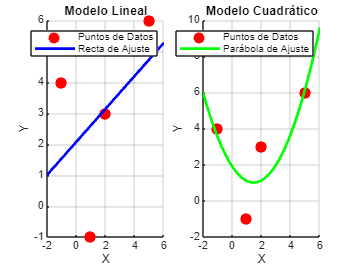


% ---------- GRAFICAR LOS RESULTADOS ----------
% Crear una figura con dos subgráficas
figure;

% Gráfica para el modelo lineal
subplot(1, 2, 1);
hold on;
grid on;
plot(X, Y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Puntos de Datos');
x_vals_lineal = linspace(min(X) - 1, max(X) + 1, 100);
y_vals_lineal = u_lineal(1) + u_lineal(2) * x_vals_lineal;
plot(x_vals_lineal, y_vals_lineal, 'b-', 'LineWidth', 2, 'DisplayName', 'Recta de Ajuste');
xlabel('X');
ylabel('Y');
title('Modelo Lineal');
legend('show');

% Gráfica para el modelo cuadrático
subplot(1, 2, 2);
hold on;
grid on;
plot(X, Y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Puntos de Datos');
x_vals_cuadratica = linspace(min(X) - 1, max(X) + 1, 100);
y_vals_cuadratica = u_cuadratica(1) + u_cuadratica(2) * x_vals_cuadratica + u_cuadratica(3) * x_vals_cuadratica.^2;
plot(x_vals_cuadratica, y_vals_cuadratica, 'g-', 'LineWidth', 2, 'DisplayName', 'Parábola de Ajuste');
xlabel('X');
ylabel('Y');
title('Modelo Cuadrático');
legend('show');